clear; clc;

%% =================================================================
%% 1. CAMERA PERCEPTION & HOMOGENEOUS TRANSFORMS
%% =================================================================
% Initialize pipeline and config
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable streams 
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

% Initialize pointcloud object
pc = realsense.pointcloud();
align_to_color = realsense.align(realsense.stream.color);

% Start pipeline
profile = pipe.start(cfg);

disp('Warming up camera...');

Warming up camera...


for i = 1:5
    fs = pipe.wait_for_frames();
    fs = align_to_color.process(fs);
    depth_frame = fs.get_depth_frame();
    color_frame = fs.get_color_frame();
    
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    vtx = points.get_vertices();
end

% Stop streaming
pipe.stop();
disp('Camera stopped. Processing final frame...');

Camera stopped. Processing final frame...



% --- Extract RGB Image ---
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);

% --- Transformation Matrix ---
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065
   -0.9999    0.0103    0.0047    0.0586
   -0.0043    0.0408   -0.9992    0.7050
         0         0         0    1.0000];

valid_depth = (vtx(:,3) > 0); 

%% =================================================================
%% 2. ARUCO MARKER DETECTION (DESTINATION TRAYS)
%% =================================================================
disp('Detecting ArUco Markers for Drop Destination...');

Detecting ArUco Markers for Drop Destination...


[markerIds, markerLocs] = readArucoMarker(I);

blue_bin_found = false;
blue_place_x = 160; % Default fallback X
blue_place_y = 0;   % Default fallback Y
blue_pixel_x = 0;
blue_pixel_y = 0;

if ~isempty(markerIds)
    for i = 1:length(markerIds)
        current_id = markerIds(i);
        corners = markerLocs(:,:,i);
        
        mask_2d = poly2mask(corners(:,1), corners(:,2), 480, 640);
        mask_1d = reshape(mask_2d', [], 1);
        
        bin_vtx = vtx(valid_depth & mask_1d, :);
        
        if ~isempty(bin_vtx)
            bin_pos_cam = mean(bin_vtx, 1);
            bin_pos_world_homog = T_world_camera * [bin_pos_cam, 1]';
            
            % We will drop in the Blue Tray (ID 0)
            if current_id == 0
                blue_place_x = bin_pos_world_homog(1) * 1000;
                blue_place_y = bin_pos_world_homog(2) * 1000;
                blue_bin_found = true;
                
                blue_pixel_x = mean(corners(:,1));
                blue_pixel_y = mean(corners(:,2));
                fprintf('Blue Tray (ID 0) Detected at World X: %.1f mm, Y: %.1f mm\n', blue_place_x, blue_place_y);
            end
        end
    end
else
    disp('No ArUco markers found in the scene! Will use default place coordinates.');
end

Blue Tray (ID 0) Detected at World X: -181.9 mm, Y: -4.6 mm



%% =================================================================
%% 3. DETECT BLUE CUBES & EVALUATE ALL TARGETS
%% =================================================================
disp('Detecting Blue Cube Targets for Multi-Pick...');

Detecting Blue Cube Targets for Multi-Pick...



hsvI = rgb2hsv(I);
H = hsvI(:,:,1); S = hsvI(:,:,2); V = hsvI(:,:,3);

hueMask = (H > 0.52) & (H < 0.65); 
level = max(graythresh(S), 0.40); 
mask = hueMask & (S > level) & (V > 0.25); 

mask = bwareaopen(mask, 100); 
mask = imfill(mask, 'holes');

% GEOMETRIC FILTERING
stats = regionprops(mask, 'Area', 'PixelIdxList', 'Solidity', 'Centroid');
robust_mask = false(size(mask));
for j = 1:length(stats)
    if stats(j).Area > 300 && stats(j).Area < 15000 && stats(j).Solidity > 0.80
        robust_mask(stats(j).PixelIdxList) = true;
    end
end
mask = robust_mask;

mask_1d = reshape(mask', [], 1);
blue_indices = valid_depth & mask_1d;
blue_vtx = vtx(blue_indices, :);

if isempty(blue_vtx)
    disp('No blue objects found in the 3D space! Aborting sequence.');
    return;
end

disp('Clustering Point Cloud to separate multiple objects...');

Clustering Point Cloud to separate multiple objects...


ptCloud = pointCloud(blue_vtx);
[labels, numClusters] = pcsegdist(ptCloud, 0.008);

if numClusters == 0
    disp('Could not find any distinct physical objects. Aborting sequence.');
    return;
end

targets = []; 
target_idx = 0;
jaw_tolerance_deg = 12.5; 

for c = 1:numClusters
    cubeIndices = find(labels == c);
    
    % Ignore tiny clusters (noise)
    if length(cubeIndices) < 150 
        continue; 
    end
    
    cubeCloud = select(ptCloud, cubeIndices);
    
    % --- Centroid Math ---
    pos_cam = mean(cubeCloud.Location, 1);
    pos_cam_homog = [pos_cam(1); pos_cam(2); pos_cam(3); 1];
    pos_world_homog = T_world_camera * pos_cam_homog;
    curr_pos_world = pos_world_homog(1:3)';
    
    % --- SWEEPING RECTANGLE ORIENTATION LOGIC ---
    points_cam_homog = [cubeCloud.Location, ones(size(cubeCloud.Location, 1), 1)]'; 
    points_world = (T_world_camera * points_cam_homog)'; 

    max_z = max(points_world(:, 3)); 
    top_face_indices = points_world(:, 3) > (max_z - 0.005);
    top_points_xy = points_world(top_face_indices, 1:2); 

    search_angles = 0:1:89;
    areas = zeros(size(search_angles));
    box_widths = zeros(size(search_angles));
    box_heights = zeros(size(search_angles));

    for a_idx = 1:length(search_angles)
        t_ang = deg2rad(search_angles(a_idx));
        u = [cos(t_ang); sin(t_ang)];
        v = [-sin(t_ang); cos(t_ang)];
        
        proj_u = top_points_xy * u;
        proj_v = top_points_xy * v;
        
        w = max(proj_u) - min(proj_u);
        h = max(proj_v) - min(proj_v);
        
        areas(a_idx) = w * h;
        box_widths(a_idx) = w;
        box_heights(a_idx) = h;
    end

    [~, min_idx] = min(areas);
    best_angle_deg = search_angles(min_idx);
    final_w = box_widths(min_idx);
    final_h = box_heights(min_idx);

    aspect_ratio = max(final_w, final_h) / min(final_w, final_h);
    is_rect = false;
    curr_angle_deg = best_angle_deg;

    if aspect_ratio > 1.3 
        is_rect = true;
        if final_h > final_w
            curr_angle_deg = mod(best_angle_deg + 90, 180);
        end
    end
    
    % --- Feasibility Math ---
    % --- Feasibility Math ---
    theta_arm_deg = rad2deg(atan2(curr_pos_world(2), curr_pos_world(1)));
    angular_diff = curr_angle_deg - theta_arm_deg;
    
    if is_rect
        % Rectangles are only symmetric every 180 degrees.
        % The arm must align with the long axis to squeeze the short sides.
        curr_angular_error = abs(mod(angular_diff + 90, 180) - 90);
    else
        % Squares are symmetric every 90 degrees.
        curr_angular_error = abs(mod(angular_diff + 45, 90) - 45);
    end
    
    is_feasible = (curr_angular_error <= jaw_tolerance_deg);
    
    % --- UI Pixel Mapping ---
    % --- NEW UI Pixel Mapping (USE THIS) ---
    % 1. Get the local indices of this cluster in the point cloud
    local_idx = find(labels == c);
    
    % 2. Map those back to the global 1D index of the camera frame
    global_blue_idx = find(blue_indices);
    cluster_global_idx = global_blue_idx(local_idx);
    
    % 3. Convert row-major 1D indices back to 2D Screen Pixels (640x480)
    cols = mod(cluster_global_idx - 1, 640) + 1; % X coordinates
    rows = floor((cluster_global_idx - 1) / 640) + 1; % Y coordinates
    
    % Get the exact center pixel of the cube for the text annotation
    pixel_x_target = mean(cols);
    pixel_y_target = mean(rows);
    
    % Save target to list
    target_idx = target_idx + 1;
    targets(target_idx).id = target_idx;
    targets(target_idx).color = 'Blue';
    targets(target_idx).pos = curr_pos_world;
    targets(target_idx).angle = curr_angle_deg;
    targets(target_idx).error = curr_angular_error;
    targets(target_idx).feasible = is_feasible;
    targets(target_idx).is_rect = is_rect;
    targets(target_idx).pixel_x = pixel_x_target;
    targets(target_idx).pixel_y = pixel_y_target;
end

if isempty(targets)
    disp('Found clusters, but none were large enough to be valid objects.');
    return;
end

%% =================================================================
%% 4. DEBUGGING / VERIFICATION TABLE & VISUALIZATION
%% =================================================================
fprintf('\n===========================================================================\n');

fprintf(' DETECTED OBJECTS REPORT \n');

 DETECTED OBJECTS REPORT 


fprintf('===========================================================================\n');

fprintf('%-5s | %-7s | %-6s | %-6s | %-6s | %-7s | %-6s | %-10s\n', ...
    'ID', 'Color', 'X(mm)', 'Y(mm)', 'Z(mm)', 'Angle', 'IsRect', 'Feasible');

ID    | Color   | X(mm)  | Y(mm)  | Z(mm)  | Angle   | IsRect | Feasible  


fprintf('---------------------------------------------------------------------------\n');

---------------------------------------------------------------------------



for i = 1:length(targets)
    t = targets(i);
    feasible_str = 'YES'; if ~t.feasible, feasible_str = 'NO'; end
    rect_str = 'NO'; if t.is_rect, rect_str = 'YES'; end
    fprintf('%-5d | %-7s | %-6.1f | %-6.1f | %-6.1f | %-7.1f | %-6s | %-10s\n', ...
        t.id, t.color, t.pos(1)*1000, t.pos(2)*1000, t.pos(3)*1000, t.angle, rect_str, feasible_str);
end

1     | Blue    | 115.4  | -40.0  | 50.6   | 131.0   | YES    | NO        
2     | Blue    | 107.0  | 61.8   | 23.6   | 119.0   | YES    | NO        
3     | Blue    | 3.0    | 143.5  | 30.8   | 54.0    | NO     | NO        


fprintf('===========================================================================\n\n');


% Create the figure window explicitly
f = figure('Name', 'Workspace Target Debug', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);
imshow(I); 
hold on;

% Draw ArUco Tray
if blue_bin_found
    plot(blue_pixel_x, blue_pixel_y, 's', 'MarkerSize', 12, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', 'b');
    text(blue_pixel_x + 20, blue_pixel_y, 'DROP TRAY (ID 0)', 'Color', 'w', 'BackgroundColor', 'k', 'FontWeight', 'bold', 'FontSize', 10);
end

% Draw Cubes
for i = 1:length(targets)
    t = targets(i);
    marker_color = 'b';
    text_bg = 'k'; if ~t.feasible, text_bg = 'r'; end
    
    plot(t.pixel_x, t.pixel_y, 'o', 'MarkerSize', 8, 'MarkerEdgeColor', 'w', 'MarkerFaceColor', marker_color);
    annot_str = sprintf('ID:%d | %d\\circ\nF:%d | R:%d', t.id, round(t.angle), t.feasible, t.is_rect);
    text(t.pixel_x + 15, t.pixel_y, annot_str, 'Color', 'w', 'BackgroundColor', text_bg, 'FontSize', 9, 'FontWeight', 'bold', 'Margin', 1);
end
hold off;

% UI Button
btn = uicontrol(f, 'Style', 'pushbutton', 'String', 'START ROBOT', 'Position', [20, 20, 150, 50], ...
    'FontSize', 12, 'FontWeight', 'bold', 'BackgroundColor', 'g', 'Callback', 'uiresume(gcbf)');

disp('Image generated. Waiting for you to click "START ROBOT" on the image window...');

Image generated. Waiting for you to click "START ROBOT" on the image window...


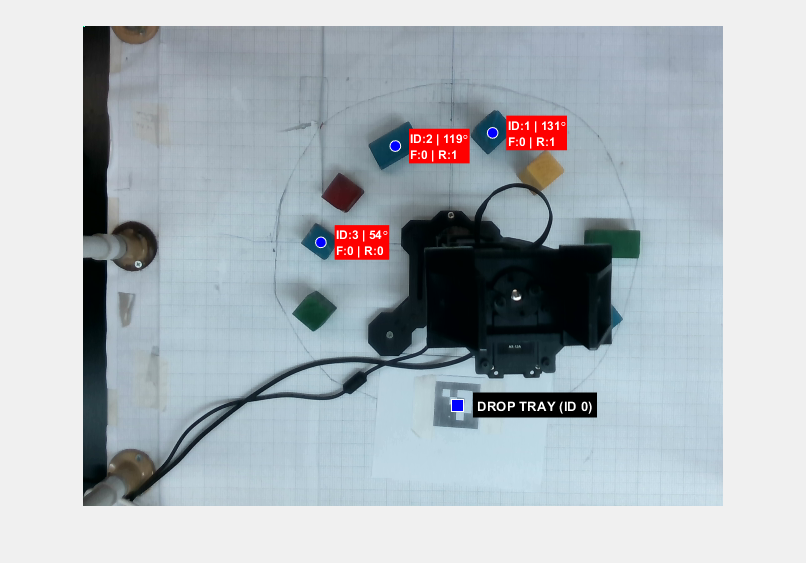

drawnow limitrate; shg; 
uiwait(f);

if isvalid(btn), delete(btn); end

disp('Button clicked! Proceeding to hardware sequence...');

Button clicked! Proceeding to hardware sequence...


drawnow; shg; 

disp('Waiting for user confirmation to proceed...');

Waiting for user confirmation to proceed...


h_msg = msgbox('Review the target map. Click OK to begin the physical sorting sequence...', 'Ready to Sort');
uiwait(h_msg); 
input('Press Enter to begin the physical sorting sequence...', 's');

%% =================================================================
%% 5. INITIALIZE ROBOT CONNECTION
%% =================================================================
port = 'COM5'; 
numServos = 5; 

try
    arb = Arbotix('port', port, 'nservos', numServos);
    fprintf('\nSuccessfully connected to Pincher on %s\n', port);
catch
    error('Could not connect. Ensure %s is free and the robot is powered on.', port);
end

serPort COM5is in use.   Closing it.


i = 4


Successfully connected to Pincher on COM5



disp('Maximizing servo stiffness (Setting Compliance Margin to 0)...');

Maximizing servo stiffness (Setting Compliance Margin to 0)...


ADDR_CW_COMPLIANCE_MARGIN = 26;
ADDR_CCW_COMPLIANCE_MARGIN = 27;

arb.writedata1(1, ADDR_CW_COMPLIANCE_MARGIN, 2);
arb.writedata1(1, ADDR_CCW_COMPLIANCE_MARGIN, 2);
arb.writedata1(2, ADDR_CW_COMPLIANCE_MARGIN, 8);
arb.writedata1(2, ADDR_CCW_COMPLIANCE_MARGIN, 8);
pause(0.5); 

% Setup Base Variables
jaw_open_val  = 34;
jaw_close_val = 28;
speed = 100;
z_offset_mm = 60; % Using 60mm offset for safe hovering above cubes

% Initial Home & Open Jaw
fprintf('Opening Jaw and Homing Robot...\n');

Opening Jaw and Homing Robot...


[~, th_open] = positionJaw(jaw_open_val);
arb.setpos(5, th_open, speed);
for i = 1:4
    arb.setpos(i, 0, speed);
end
pause(3);

%% =================================================================
%% 6. AUTOMATED MULTI-PICK SEQUENCE WITH DROPPING
%% =================================================================
drop_z = 120; % FIXED DROP HEIGHT IN MM

for i = 1:length(targets)
    t = targets(i);
    
    if ~t.feasible
        fprintf('Cube [%d] cannot be picked up due to angle (Error: %.1f deg)\n', t.id, t.error);
        continue; 
    end
    
    fprintf('\n======================================\n');
    fprintf('Executing Pick & Drop for Box [%d]...\n', t.id);
    fprintf('======================================\n');
    
    pos_world = t.pos;
    pick_x = pos_world(1) * 1000;
    pick_y = pos_world(2) * 1000;
    pick_z = pos_world(3) * 1000;

    pick  = [pick_x, pick_y, pick_z, deg2rad(175)];  
    drop_pos = [blue_place_x, blue_place_y, drop_z, deg2rad(175)];    

    pre_pick  = pick  + [0, 0, z_offset_mm, 0];
    
    try
        fprintf('Moving to Pre-Pick...\n');
        moveRobotToTarget(arb, pre_pick, speed, 2); 

        fprintf('Moving down to Pick...\n');
        moveRobotToTarget(arb, pick, speed, 2);     

        fprintf('Closing Jaw...\n');
        [~, th_close] = positionJaw(jaw_close_val);
        arb.setpos(5, th_close, speed);
        pause(2);

        fprintf('Moving up to Pre-Pick and Homing...\n');
        moveRobotToTarget(arb, pre_pick, speed, 2);
        for j = 1:4
            arb.setpos(j, 0, speed);
        end
        pause(2);

        fprintf('Moving to Drop Position (Over Tray, Height: %d mm)...\n', drop_z);
        moveRobotToTarget(arb, drop_pos, speed, 2);

        fprintf('Opening Jaw to DROP...\n');
        arb.setpos(5, th_open, speed);
        pause(2);

        fprintf('Returning to Home...\n');
        for j = 1:4
            arb.setpos(j, 0, speed);
        end
        pause(2); 
        
    catch ME
        fprintf('\n--> ERROR: Sequence failed for Box [%d].\n', t.id);
        fprintf('--> REASON: %s\n', ME.message);
        fprintf('--> Safely returning to Home and skipping to next cube...\n');
        
        arb.setpos(5, th_open, speed);
        for j = 1:4
            arb.setpos(j, 0, speed);
        end
        pause(2);
        continue;
    end
end

Cube [1] cannot be picked up due to angle (Error: 29.9 deg)
Cube [2] cannot be picked up due to angle (Error: 89.0 deg)
Cube [3] cannot be picked up due to angle (Error: 34.8 deg)



fprintf('\nAll feasible cubes processed. Sequence Complete!\n');


All feasible cubes processed. Sequence Complete!



%% =================================================================
%% LOCAL HELPER FUNCTIONS
%% =================================================================
function moveRobotToTarget(arb, target, speed, pause_time)

    fullConfig = zeros(1, 4);
    for i = 1:4
        pos = arb.getpos(i);
        if ~isempty(pos)
            fullConfig(i) = pos;
        end
    end
    
    % --- THE COMBINED FRAME CALIBRATION ---
    dx = 7.896;  
    dy = -0.885;  
    x_shifted = target(1) + dx;
    y_shifted = target(2) + dy;
    
    angle_offset_deg =-1.104; %-1.944; 
    theta = deg2rad(angle_offset_deg);
    
    x_corrected = x_shifted * cos(theta) - y_shifted * sin(theta);
    y_corrected = x_shifted * sin(theta) + y_shifted * cos(theta);
    
    % ==========================================
    % PURE MATH DYNAMIC PHI 
    % ==========================================
    theta1_ideal_deg = rad2deg(atan2(y_corrected, x_corrected));
    
    if theta1_ideal_deg > -45 && theta1_ideal_deg <= 135
        dynamic_phi_deg = 175;    
    else
        dynamic_phi_deg = 185;
    end
    
    radius = sqrt(x_corrected^2 + y_corrected^2);
    if radius > 185
        dynamic_phi_deg = 180; 
    end
    
    dynamic_phi = deg2rad(dynamic_phi_deg);

    solutions = findSolution(x_corrected, y_corrected, target(3), dynamic_phi, fullConfig);
    
    if isempty(solutions)
        error('IK Solver failed: No valid joint angles found for this target.');
    end
    
    for joint = 1:4
        arb.setpos(joint, solutions(joint), speed);
    end
    pause(pause_time);
end